# Mechanical Nonlinear Model of a double inverted pendulum on rails

Professor:  Dr. Helon Vicente Hultmann Ayala (helon@puc-rio.br)

## 1. Problem definition

For the current iteration of this problem, consider the the double inverted pendulum shown next.

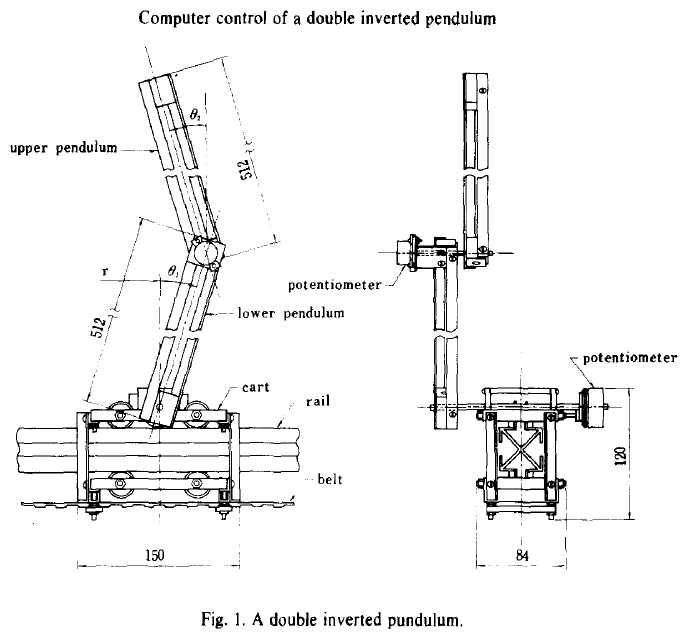

Source: K. Furuta, T. Okutani, H. Sone, Computer control of a double inverted pendulum, Computers & Electrical Engineering, Volume 5, Issue 1, 1978, Pages 67-84, ISSN 0045-7906, [https://doi.org/10.1016/0045-7906(78)90018-6.](https://doi.org/10.1016/0045-7906(78)90018-6.)

The state variables are

- $x$: Position on the cart on the rails;

- $\theta_1$: Angle between the vertical and the lower pendulum;

- $\theta_2$: Angle between the vertical and the upper pendulum.

For the space-state representation, we use the following convention


$$\pmatrix{\dot q_1\cr\dot q_2\cr\dot q_3\cr q_1\cr q_2\cr q_3}=\pmatrix{\dot x\cr\dot\theta_1\cr\dot\theta_2\cr x\cr\theta_1\cr\theta_2}$$


In what follows, we use this naming convention:

- No index: cart;

- Index 1: Lower pendulum;

- Index 2: Upper pendulum.

## 2. Pre-processing

Cleaning variables, console and closing windows.

clear all
close all
clc

### 2.a Symbolic variables

First we define some constants and the independent variable t.

% Mass
syms M0 M1 M2
% Length of each pendulum
syms L1 L2
% Distance from the joint to center of mass
syms l1 l2 
% Moment of inertia
syms J1 J2 
% Friction constant of the cart and pendulums
syms F0 F1 F2
% Applied force on the cart
syms F
% Time and gravity
syms t g

Now we define the generalized coordinates and their derivatives. These are used in the Euler-Lagrange equations and later adapted into the state-space representation

% ndof: Degrees of freedom
ndof = 3;

Note: Here, we define the quantities as row vectos, i.e., $q=[x\quad\theta_1\quad\theta_2]$.

% Generalized coordinates
q   = sym('q',[1 ndof]);
% Generalized velocities
qp  = sym('qp',[1 ndof]);
% Generalized accelerations
qpp = sym('qpp',[1 ndof]);

Next, we define the same quantities as a function of time. This is necessary for computing the derivatives correctly in the next steps. These vectors are the generalized coordinates as functions of time in the form $q(t)=[x(t)\quad\theta_1(t)\quad\theta_2(t)]$.

% Generalized coordinates (as a function of time)
qt   = arrayfun(@(i) str2sym(sprintf('q%d(t)',i)),1:ndof);
% Generalized velocities (as a function of time)
qpt  = arrayfun(@(i) str2sym(sprintf('q%dp(t)',i)),1:ndof);
% Generalized accelerations (as a function of time)
qppt = arrayfun(@(i) str2sym(sprintf('q%dpp(t)',i)),1:ndof);

In order to go from the notation $q(t)$ (useful during the derivation) to simply $q$ (easier to read, and transform into state-space representation at the end), we define the first and second derivates explicitly:

% First derivatives of qt w.r.t. t (generalized velocities)
qpt_diff  = diff(qt,t);
% Ssecond derivatives of qt w.r.t. t (generalized accelerations)
qppt_diff = diff(qpt,t);

## 3. System description

In this section we define the quantities used to compute the terms needed in the Euler-Lagrange equations.

### 3.a Position

Notice that we consider theta to increase clockwise.

% Horizontal position of each center of mass
x = q(1);
x1 = x + l1*sin(q(2));
x2 = x + L1*sin(q(2)) + l2*sin(q(3));
% Vertical position of each center of mass
y = sym(0);
y1 = y + l1*cos(q(2));
y2 = y + L1*cos(q(2)) + l2*cos(q(3));

### 3.b Velocity

Deriving each component of the position yields:

% Velocity of each center of mass (vx = horizontal component)
xp = qp(1);
x1p = xp + l1*cos(q(2))*qp(2);
x2p = xp + L1*cos(q(2))*qp(2) + l2*cos(q(3))*qp(3);
% Velocity of each center of mass (vy = vertical component)
yp = sym(0);
y1p = -yp - l1*sin(q(2))*qp(2);
y2p = -yp - L1*sin(q(2))*qp(2) - l2*sin(q(3))*qp(3);

### 3.c Energy + Exogenous/Dissipative terms

Now we define the following terms:

- T: Kinetic energy;

- V: Potential energy;

- Tau: Exogenous (generalized forces)+Dissipative terms;

% Kinetic energy = 1/2*[mass*velocity²+(moment of inertia)*(angular velocity)²]
T = 1/2*( ...
  M0*(xp^2+yp^2)+ ...
  M1*(x1p^2+y1p^2)+ J1*qp(2)^2+...
  M2*(x2p^2+y2p^2)+ J2*qp(3)^2);
% Potential energy: mass*gravity*height
V = ...
  M0*g*y+ ...
  M1*g*y1+ ...
  M2*g*y2;
% Exogenous term: F acts on q1 only
% Dissipative terms: proportional to qp(i) by a factor -F_(i-1)
Tau = [F-F0*qp(1);-F1*qp(2);-F2*qp(3)]

$$Tau = \left(\begin{array}{c} F-F_{0}\,{\mathrm{qp}}_{1}\\ -F_{1}\,{\mathrm{qp}}_{2}\\ -F_{2}\,{\mathrm{qp}}_{3} \end{array}\right)$$

% Lagrangian: Kinetic - Potential
L = T - V;

## 4. Obtaining equations of motion

We compute each term and write the equations of motion from the Euler-Lagrange (EL) equations:


$$\frac{\partial\mathcal{L}}{\partial q_i}+\frac{d}{dt}\frac{\partial\mathcal{L}}{\partial \dot q_i}=\tau_i$$


For the space-state representation, we will need the acceleration , which is done simultaneously.

% These arrays will hold the equations/expressions
eq = sym(zeros(ndof,1)); % Full EL equation for each generalized coordinate
acc = sym(zeros(ndof,1)); % Previous variable eq(i) solved for the acceleration qpp(i)
% Loop through the generalized coordinates
for i=1:ndof    
    % Derivative of L w.r.t. q(i)
    der_q = simplify(diff(L,q(i)));  
    
    % Derivative of L w.r.t. qp(i) (only T in L=T-V depends on qp though)
    der_qp = simplify(diff(T,qp(i)));   
    % Subs the generalized coordinates for their respective time functions    
    der_qp = subs(der_qp,[q qp qpp],[qt qpt qppt]); 
    % This lets us properly differentiate w.r.t. time t
    der_qp = diff(der_qp,t);
    % And return to the simpler to read variables q, qp and qpp
    der_qp = subs(der_qp,[qt qpt qpt_diff qppt_diff],[q qp qp qpp]); % retorna às variaveis originais
    
    % The EL are as follows
    eq(i) = [der_qp - der_q == Tau(i)];
    
    % And solving for the acceleration qpp(i) yields:
    acc(i) = [rhs(isolate(eq(i),qpp(i)))];   
end

We can represent the dynamics of this system in matrix form as follows


$$\mathbf{M}\ddot{\mathbf{q}}+\mathbf{C}\dot{\mathbf{q}}=\mathbf{F}$$


where 

- $\mathbf{M}$ is the mass matrix;

- $\mathbf{C}$ is the damping matrix;

- $\mathbf{F}$ is the exogenous term vector (only $F$ in the 1st component);

For our purposes, we can compute $\mathbf{M$ as follows:

[M,vec] = equationsToMatrix(expand(eq),qpp);
M = simplify(M);
% Symbolic variables used for display only
syms x theta1 theta2 x_dot theta_dot_1 theta_dot_2
subs(M,[q qp],[x theta1 theta2 x_dot theta_dot_1 theta_dot_2])

$$ans = \begin{array}{l} \left(\begin{array}{ccc} M_{0}+M_{1}+M_{2} & \sigma_{1} & M_{2}\,l_{2}\,\cos\left(\theta_{2}\right)\\ \sigma_{1} & M_{2}\,{L_{1}}^{2}+M_{1}\,{l_{1}}^{2}+J_{1} & L_{1}\,M_{2}\,l_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)\\ M_{2}\,l_{2}\,\cos\left(\theta_{2}\right) & L_{1}\,M_{2}\,l_{2}\,\cos\left(\theta_{1}-\theta_{2}\right) & M_{2}\,{l_{2}}^{2}+J_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\left(M_{1}\,l_{1}+L_{1}\,M_{2}\right) \end{array}$$

We can check with the reference which yields exactly the same result

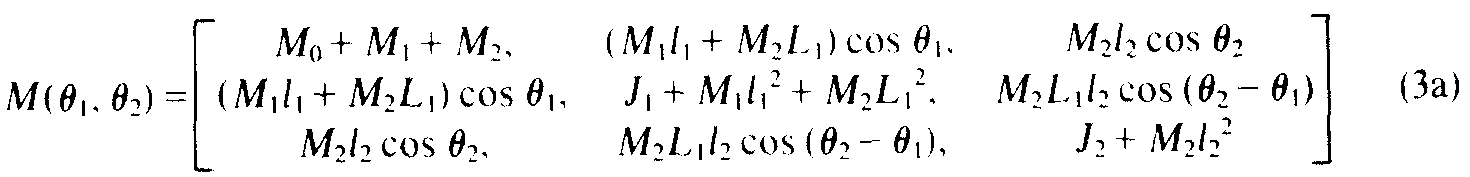

For completeness, we can compute the friction terms

% Write the dynamic equations as eqs == 0
eqs = lhs(eq)-rhs(eq);
% Subtract the influence from the term Mass*qpp and simplify it
eqs = simplify(eqs - M*qpp.',10)

$$eqs = \left(\begin{array}{c} F_{0}\,{\mathrm{qp}}_{1}-F-L_{1}\,M_{2}\,{{\mathrm{qp}}_{2}}^{2}\,\sin\left(q_{2}\right)-M_{1}\,l_{1}\,{{\mathrm{qp}}_{2}}^{2}\,\sin\left(q_{2}\right)-M_{2}\,l_{2}\,{{\mathrm{qp}}_{3}}^{2}\,\sin\left(q_{3}\right)\\ L_{1}\,M_{2}\,l_{2}\,\sin\left(q_{2}-q_{3}\right)\,{{\mathrm{qp}}_{3}}^{2}+F_{1}\,{\mathrm{qp}}_{2}-L_{1}\,M_{2}\,g\,\sin\left(q_{2}\right)-M_{1}\,g\,l_{1}\,\sin\left(q_{2}\right)\\ -L_{1}\,M_{2}\,l_{2}\,\sin\left(q_{2}-q_{3}\right)\,{{\mathrm{qp}}_{2}}^{2}+F_{2}\,{\mathrm{qp}}_{3}-M_{2}\,g\,l_{2}\,\sin\left(q_{3}\right) \end{array}\right)$$

% Output the full matrix
C = subs(eqs,[q qp],[x theta1 theta2 x_dot theta_dot_1 theta_dot_2])

$$C = \left(\begin{array}{c} F_{0}\,\dot{x}-F-L_{1}\,M_{2}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)-M_{1}\,l_{1}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)-M_{2}\,l_{2}\,{{\dot{\theta }}_{2}}^{2}\,\sin\left(\theta_{2}\right)\\ L_{1}\,M_{2}\,l_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)\,{{\dot{\theta }}_{2}}^{2}+F_{1}\,{\dot{\theta }}_{1}-L_{1}\,M_{2}\,g\,\sin\left(\theta_{1}\right)-M_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right)\\ -L_{1}\,M_{2}\,l_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)\,{{\dot{\theta }}_{1}}^{2}+F_{2}\,{\dot{\theta }}_{2}-M_{2}\,g\,l_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

If one collects the terms in function of the velocy vector $\dot{\mathbf{q}}=[\dot x\quad\dot\theta_1\quad\dot\theta_2]^T$, it could be verified that it yields the same dampening matrix as the reference

## 5. State-space representation

Now, we can transform the model into a state-space representation. First, we define the following state vector such as:

% State vector
x = [qp(:);q(:)];